I=imread("Skan_20241005-1445.jpg");
Ibin=rgb2gray(I);
ikor=imadjust(Ibin)

ikor = 3692×2207 uint8 matrix
   132   130   129   128   128   129   132   133   126   126   128   128   128   128   129   129   128   128   128   128   128   128   128   128   125   125   126   126   128   129   129   130   130   130   130   130   130   130   130   130   130   130   130   129   129   128   128   128   128   126
   132   130   128   126   126   129   130   132   126   126   128   128   128   128   129   129   128   128   128   128   128   128   128   128   126   126   128   128   129   129   129   130   130   130   130   130   130   130   130   130   129   129   129   129   128   128   128   126   128   128
   130   129   128   126   126   128   129   130   126   126   128   128   128   128   129   129   128   128   128   128   128   128   128   128   129   129   129   129   129   129   129   129   130   130   130   130   130   130   130   130   129   128   128   128   128   126   126   126   128   128
   129   129   128   126   126   126   128   128   126   126   128 


ib=imbinarize(ikor);
img=medfilt2(ib,[3,3])

img = 3692×2207 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

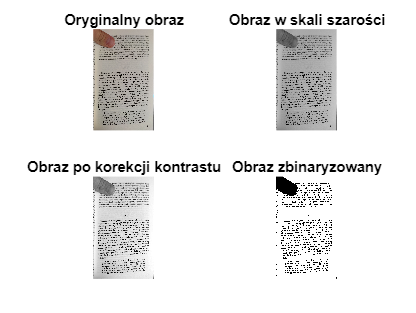



figure
subplot(2,2,1)
imshow(I)
title("Oryginalny obraz")
subplot(2,2,2)
imshow(Ibin)
title("Obraz w skali szarości")
subplot(2,2,3)
imshow(ikor)
title("Obraz po korekcji kontrastu")
subplot(2,2,4)
imshow(ib)
title("Obraz zbinaryzowany")

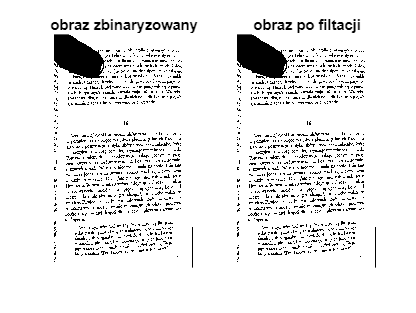


figure
subplot(1,2,1)
imshow(ib)
title("obraz zbinaryzowany")
subplot(1,2,2)
imshow(img)
title("obraz po filtacji")

I=imread("photoforcharts.png")

I = 480×640×3 uint8 array
I(:,:,1) =

   193   192   192   193   194   194   195   196   195   195   195   196   197   197   196   197   197   198   198   198   199   199   198   199   199   199   199   199   200   199   199   200   201   200   200   201   200   201   200   201   201   202   202   202   202   202   203   202   202   203   202   201   201   202   201   202   200   201   202   203   202   202   202   203   203   202   204   204   204   205   205   205   205   205   205   203   203   203   203   204   204   205   204   205   205   204   205   206   206   207   207   207   207   207   207   206   206   206   206   205   205   205   205   205   206   206   206   207   207   207   208   207   208   209   209   209   209   209   209   209   208   208   208   208   208   208   209   209   208   209   209   209   209   208   209   209   209   209   209   210   210   210   209   209   210   210   210   210   210   211   211   211   211   212   211   211   212   212   211   213  

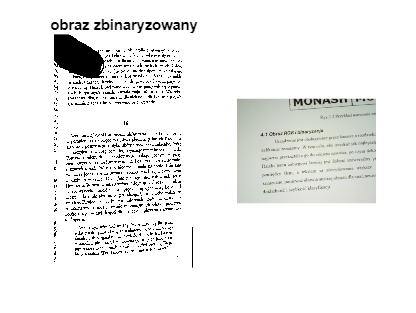

I=flip(I,1);
imshow(I)

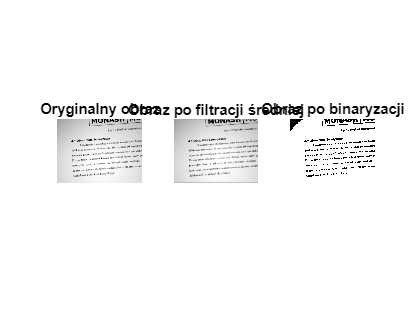


Igray=rgb2gray(I);
Igray=imadjust(Igray);
tic;
% Definicja filtra średniej
mean_filter = ones(3, 3) / 9; % 3x3 maska średniej

% Zastosowanie filtra
filtered_img = imfilter(Igray, mean_filter);
I_bin1=imbinarize(filtered_img);

% Wyświetlenie wyników
figure;
subplot(1, 3, 1), imshow(Igray), title('Oryginalny obraz');
subplot(1, 3, 2), imshow(filtered_img), title('Obraz po filtracji średniej');
subplot(1,3,3), imshow(I_bin1), title("Obraz po binaryzacji");

time1=toc;

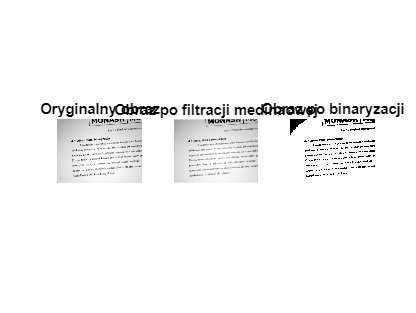

tic;
med_I=medfilt2(Igray,[5 5]);
I_bin2=imbinarize(med_I);
figure
subplot(1,3,1), imshow(Igray), title("Oryginalny obraz");
subplot(1,3,2) , imshow(med_I), title("Obraz po filtracji medinaowej");
subplot(1,3,3), imshow(I_bin2), title("Obraz po binaryzacji");

time2=toc;

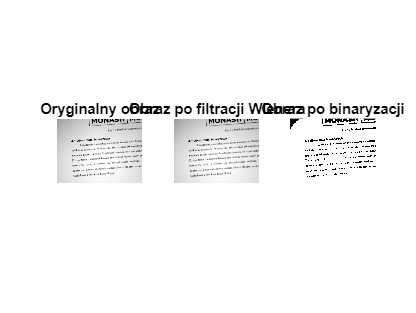

tic;
wien=wiener2(Igray,[5 5]);
I_bin3=imbinarize(wien);

figure
subplot(1,3,1), imshow(Igray), title("Oryginalny obraz");
subplot(1,3,2) , imshow(wien), title("Obraz po filtracji Wienera");
subplot(1,3,3), imshow(I_bin3), title("Obraz po binaryzacji");

time3=toc;

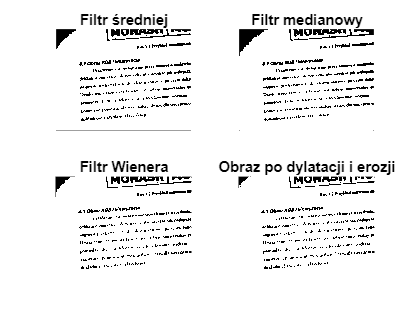

figure
subplot(2,2,1), imshow(I_bin1),title("Filtr średniej");
subplot(2,2,2), imshow(I_bin2),title("Filtr medianowy");
subplot(2,2,3), imshow(I_bin3), title("Filtr Wienera");
subplot(2,2,4), imshow(bw), title("Obraz po dylatacji i erozji")

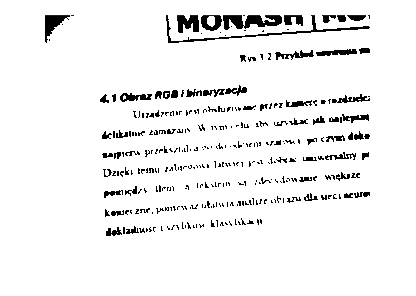

tic;
figure
I_bin4=imbinarize(Igray);

bw=bwareaopen(I_bin4,30);
imshow(bw)

time4=toc;

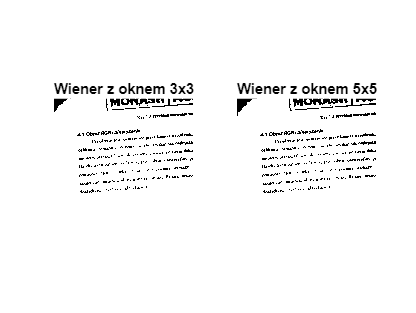

winer33=wiener2(Igray,[3 3]);
winer55=wiener2(Igray,[5 5]);

winer77=wiener2(Igray,[7 7]);
winer99=wiener2(Igray,[9 9]);

winer1515=wiener2(Igray,[15 15]);
winer2121=wiener2(Igray,[21 21]);

binwiner33=imbinarize(winer33);
binwiner55=imbinarize(winer55);

binwiner77=imbinarize(winer77);
binwiner99=imbinarize(winer99);

binwiner1515=imbinarize(winer1515);
binwiner2121=imbinarize(winer2121);
figure
subplot(1,2,1), imshow(binwiner33), title("Wiener z oknem 3x3");
subplot(1,2,2),imshow(binwiner55), title("Wiener z oknem 5x5");

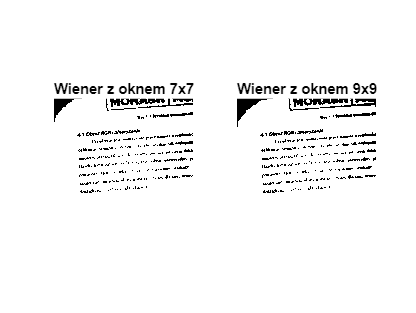


figure
subplot(1,2,1), imshow(binwiner77), title("Wiener z oknem 7x7");
subplot(1,2,2),imshow(binwiner99), title("Wiener z oknem 9x9");

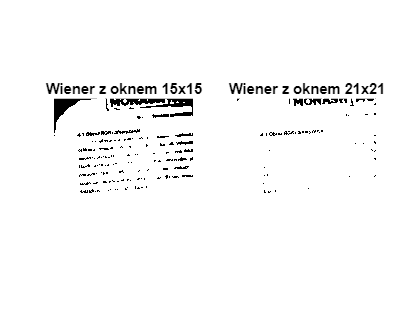


figure
subplot(1,2,1), imshow(binwiner1515), title("Wiener z oknem 15x15");
subplot(1,2,2),imshow(binwiner2121), title("Wiener z oknem 21x21");

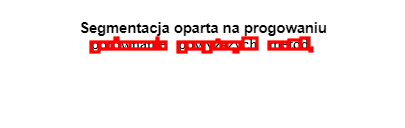

tic;
% Wczytanie obrazu - zmień nazwę pliku na własny.
I = imread('test_segment.png');

% Jeśli obraz jest kolorowy, przekształć go do skali szarości
if size(I,3) == 3
    I_gray = rgb2gray(I);
else
    I_gray = I;
end

% Progowanie metodą Otsu - automatyczne wyznaczenie progu
level = graythresh(I_gray);
BW = imbinarize(I_gray, level);

% Jeżeli tło jest czarne, a litery białe, a chcemy odwrotnie - odwracamy obraz
% Zakładamy, że chcemy, by litery były '1' (białe), a tło '0' (czarne).
% Jeśli litery są czarne, a tło jasne po progowaniu, może być konieczne odwrócenie:
% Sprawdź średnią wartość BW. Jeśli litery są ciemne, obraz będzie miał więcej jedynek w tle.
% W razie potrzeby:
if mean(BW(:)) > 0.5
    BW = ~BW;
end

% Teraz BW to binarny obraz z literami jako '1'.
% Wyszukaj obszary liter i oblicz dla nich bounding box
[L, num] = bwlabel(BW);
props = regionprops(L, 'BoundingBox');

% Wyświetlenie oryginalnego obrazu i zaznaczenie liter prostokątami
figure; imshow(I); title('Segmentacja oparta na progowaniu'); hold on;
for k = 1:length(props)
    bb = props(k).BoundingBox;
    rectangle('Position', bb, 'EdgeColor', 'r', 'LineWidth', 2);
end
hold off;

time1=toc;

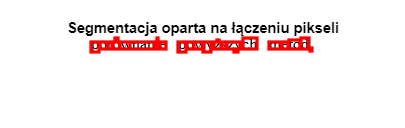

tic;
% Wczytanie obrazu (zmień nazwę pliku, jeśli używasz własnego obrazu)
I = imread('test_segment.png');

% Konwersja do skali szarości, jeśli obraz jest kolorowy
if size(I,3) == 3
    I_gray = rgb2gray(I);
else
    I_gray = I;
end

% Progowanie metodą Otsu, aby uzyskać obraz binarny
level = graythresh(I_gray);
BW = imbinarize(I_gray, level);

% Opcjonalnie odwrócenie obrazu, jeśli litery są w negatywie
if mean(BW(:)) > 0.5
    BW = ~BW;
end

% Znalezienie spójnych komponentów
CC = bwconncomp(BW, 8); % 8-sąsiedztwo

% Utworzenie macierzy etykiet
L = labelmatrix(CC);

% Wykorzystanie regionprops do uzyskania bounding boxów dla poszczególnych komponentów
props = regionprops(L, 'BoundingBox');

% Wyświetlenie oryginalnego obrazu
figure; imshow(I); title('Segmentacja oparta na łączeniu pikseli'); hold on;

% Rysowanie czerwonych prostokątów wokół każdej zidentyfikowanej litery
for k = 1:length(props)
    bb = props(k).BoundingBox;
    rectangle('Position', bb, 'EdgeColor', 'r', 'LineWidth', 2);
end

hold off;

time2=toc;

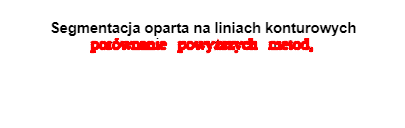

tic;
% Wczytanie obrazu (zamień 'test_segment.png' na własną nazwę pliku)
I = imread('test_segment.png');

% Konwersja do skali szarości, jeśli obraz jest kolorowy
if size(I,3) == 3
    I_gray = rgb2gray(I);
else
    I_gray = I;
end

% Progowanie metodą Otsu, aby uzyskać obraz binarny
level = graythresh(I_gray);
BW = imbinarize(I_gray, level);

% Jeśli tło jest białe, a obiekty ciemne i chcesz odwrócić, zrób to:
if mean(BW(:)) > 0.5
    BW = ~BW;
end

% Znajdowanie konturów za pomocą bwboundaries
% Zwraca listę współrzędnych (x,y) pikseli należących do granicy każdej składowej
boundaries = bwboundaries(BW, 'noholes');

% Wyświetlenie oryginalnego obrazu
figure; imshow(I); title('Segmentacja oparta na liniach konturowych'); hold on;

% Rysowanie konturów na obrazie
for k = 1:length(boundaries)
    b = boundaries{k};
    plot(b(:,2), b(:,1), 'r', 'LineWidth', 2);
end

hold off;

time3=toc;

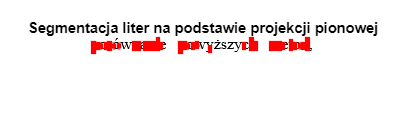

tic;
% Wczytanie obrazu
I = imread('test_segment.png');

% Konwersja do skali szarości
if size(I,3) == 3
    I_gray = rgb2gray(I);
else
    I_gray = I;
end

% Progowanie metodą Otsu
level = graythresh(I_gray);
BW = imbinarize(I_gray, level);

% Odwrócenie, jeśli tło jest ciemne
if mean(BW(:)) > 0.5
    BW = ~BW;
end

% Opcjonalna erozja, aby poszerzyć przerwy między literami
se = strel('line', 2, 90); % pionowy element strukturalny
BW_eroded = imerode(BW, se);

% Projekcja pionowa
verticalProjection = sum(BW_eroded, 1);

% Ustalmy próg, np. 2 piksele. Jeżeli kolumna ma ≤ 2 piksele, traktujemy ją jako przerwę.
gapThreshold = 2;
gapIndices = find(verticalProjection <= gapThreshold);

% Znajdź segmenty liter na podstawie przerw
wordBoundaries = [];
if ~isempty(gapIndices)
    prevGap = 1;
    for i = 1:length(gapIndices)-1
        if gapIndices(i+1) - gapIndices(i) > 1
            startCol = gapIndices(i) + 1;
            endCol = gapIndices(i+1) - 1;
            wordBoundaries = [wordBoundaries; startCol, endCol]; %#ok<AGROW>
        end
    end
    
    % Sprawdź początek i koniec
    if gapIndices(1) > 1
        wordBoundaries = [1, gapIndices(1)-1; wordBoundaries];
    end
    if gapIndices(end) < size(BW_eroded,2)
        wordBoundaries = [wordBoundaries; gapIndices(end)+1, size(BW_eroded,2)];
    end
else
    % Brak przerw - cały wiersz to jedna "litera" lub bez rozdzielenia
    wordBoundaries = [1, size(BW_eroded,2)];
end

% Wyznaczenie bounding boxów dla każdej litery
figure; imshow(I); title('Segmentacja liter na podstawie projekcji pionowej'); hold on;
for k = 1:size(wordBoundaries,1)
    leftCol = wordBoundaries(k,1);
    rightCol = wordBoundaries(k,2);
    
    % Dla wybranego segmentu znajdź minimalny i maksymalny wiersz zawierający piksele
    subWord = BW(:, leftCol:rightCol);
    rowsWithText = find(sum(subWord,2) > 0);
    
    if ~isempty(rowsWithText)
        topRow = min(rowsWithText);
        bottomRow = max(rowsWithText);
        
        rectX = leftCol;
        rectY = topRow;
        rectWidth = (rightCol - leftCol + 1);
        rectHeight = (bottomRow - topRow + 1);
        
        % Rysuj czerwony prostokąt wokół litery
        rectangle('Position', [rectX, rectY, rectWidth, rectHeight], 'EdgeColor', 'r', 'LineWidth', 2);
    end
end
hold off;

time4=toc;

addpath("polskie_znaki\A\")
a1=imread("A_13.png")

a1 = 28×28 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   25

a2=imread("A_243.png")

a2 = 28×28 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   25

a3=imread("A_1893.png")

a3 = 28×28 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   25

a4=imread("A_93.png")

a4 = 28×28 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   25

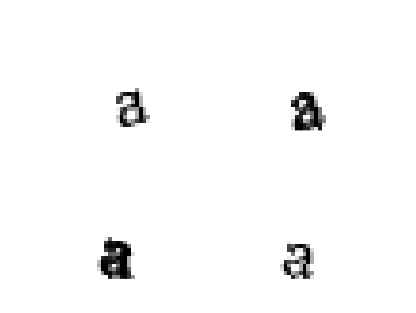


figure
subplot(2,2,1); imshow(a1);
subplot(2,2,2); imshow(a2);
subplot(2,2,3); imshow(a3);
subplot(2,2,4); imshow(a4);


result=ocr(I);
text=result.Text;
disp(text)

l MOINADEE |

Rys 3 7 Przykiad usuwama 52

4.10braz RGB binaryzacja

+ obshugrwane przez kamers o rozdaelc:

clu, aby uzyskac jak najlepsza

Uszadzeme jes

delikatmie Zamazany W tym ¢

pajpierw przeksztalca go 40 dciens szaroics, po czym doko

Dzigks temu zabiegow latwiey jest dobre uniwersalny Pf

pomicdzy flem, a tekstem 53 rdecydowame wigksze

Konieczne, poniewaz ula analize obrazu dla sieci neuro

dokladnos i szybkoié Klasyfikach


